# LAB3 - Linear Convolution 

#### **Def:**In a linear time invariant (LTI) system, the response of system can be calculated from the input x(n) and the impulse response h(n).

### Assignment 4.1

%the system has the impulse response h1(n) = u(n-10) – u(n-20)
x = stepseq(30, 0, 100) - stepseq(50, 0, 100)

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


h1 = stepseq(10, 0, 100) - stepseq(20, 0, 100)

h =      0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y = conv(x, h1)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     2     3     4     5     6     7     8


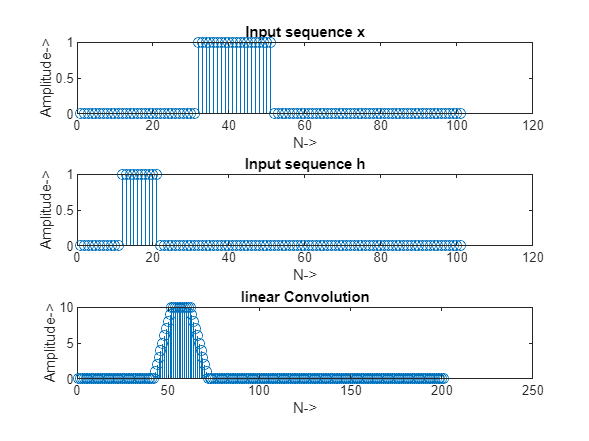


subplot(3,1,1);
stem(x);
ylabel('Amplitude');
xlabel('N');
title('Input sequence x')

subplot(3,1,2);
stem(h1);
ylabel('Amplitude');
xlabel('N');
title('Input impulse response h1(n)')

subplot(3,1,3);
stem(y);
ylabel('Amplitude');
xlabel('N');
title('Linear Convolution');

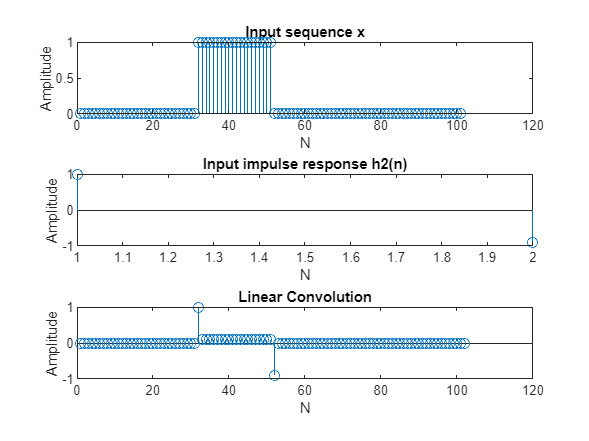

%the system has the impulse response h2(n) = (0.9)^nu(n) 
n = 0:101; 
x = stepseq(30, 0, 100) - stepseq(50,0,100);
h2 = [1,-0.9];
y = conv(a,x);

subplot(3,1,1);
stem(x);
ylabel('Amplitude');
xlabel('N');
title('Input sequence x')

subplot(3,1,2);
stem(h2);
ylabel('Amplitude');
xlabel('N');
title('Input impulse response h2(n)')

subplot(3,1,3);
stem(y);
ylabel('Amplitude');
xlabel('N');
title('Linear Convolution');

%the system has the impulse response h3(n) = δ(n) – δ(n-1) 
x = stepseq(30, 0, 100) - stepseq(50,0,100);
h3 = impseq(0, 0, 100) - impseq(1, 0, 100)

h3 =      1    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


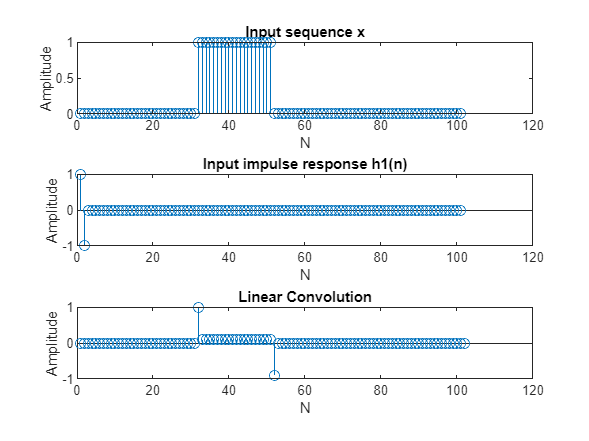


subplot(3,1,1);
stem(x);
ylabel('Amplitude');
xlabel('N');
title('Input sequence x')

subplot(3,1,2);
stem(h3);
ylabel('Amplitude');
xlabel('N');
title('Input impulse response h1(n)')

subplot(3,1,3);
stem(y);
ylabel('Amplitude');
xlabel('N');
title('Linear Convolution');

### Assignment 4.2: Matrix-vector Multiplication to perform Linear Convolution

% - Determine the linear convolution y(n) = x(n)*h(n)
% - Express x(n) as a 4x1 column vector x and y(n) as a 6x1 column vector y. Now
% determine the 6x4 matrix H so that y = Hx
% - Characterize the matrix H. Can you give the definition of a Toeplitz matrix?
% - What can you say about the first column and the first row of H?
x = [1 2 3 4]'

x =      1     2     3     4


h = [3 2 1]'

h =      3     2     1


y = conv(x, h)

y =      3     8    14    20    11     4


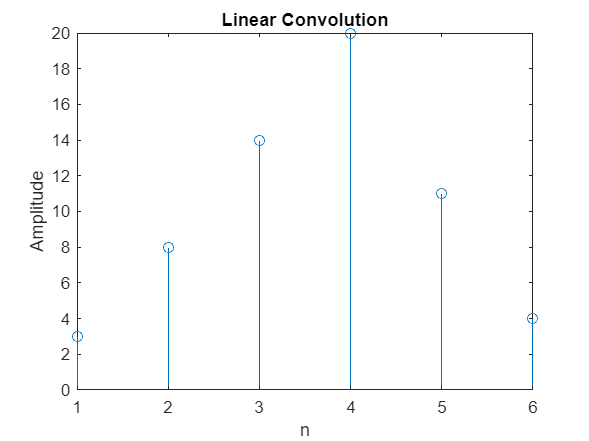

subplot(1,1,1)
stem(y), ylabel("Amplitude"), xlabel("n"), title("Linear Convolution")

### Assignment 3: Z-transform and Inverse Z-Transform

function [x, n] = stepseq(n0, n1, n2)
%x(n) = u(n-n0);
%n1 <= n <= n2;
%[x, n] = stepseq(n0, n1, n2);

n = n1:n2;
x = (n-n0) > 0;
end

function [x,n] = impseq(n0,n1,n2)
%x(n) = delta(n-n0); 
%n1 <= n <= n2;
% ----------------------------------------------
%[x,n] = impseq(n0,n1,n2);

n = n1:n2; 
x = (n-n0) == 0;
end 

function [y,H]=conv_tp(h,x)

% Linear Convolution using Toeplitz Matrix
% [y,H] = conv_tp(h,x)
% y = output sequence in column vector form
% H= Toeplitz matrix corresponding to sequence h so that y = Hx
% h = Impulse response sequence in column vector form
% x = input sequence in column vector form

Nx = length(x);
%Nh = length(h);
hc=[h; zeros(Nx-1,1)];
hr=[h(1),zeros(1,Nx-1)];
H=Toeplitz(hc,hr);
y=H*x;
end

function H = Toeplitz(hc,hr)
    H = hc;
    for count = 1 : (length(hr)-1)
        m = [zeros(count,1) ; hc(1:length(hc) - count)];
        H = [H,m];
    end
    
end
